function Mapset = createMapset()
    characters = ['a':'z', ' ', '.', ',', '!', '"', ';'];
    Mapset = cell(32,2);
    for i = 1:length(characters)
        Mapset{i,1} = characters(i);
        Mapset{i,2} = dec2bin(i-1,5); 
    end
end

function bits_Mapset = createBitsMapset(bit_rate)
    bits_Mapset = cell(2^bit_rate, 1);
    for i = 1:2^bit_rate
        bits_Mapset{i} = dec2bin(i - 1, bit_rate);
    end
end

function thresholds = get_thresholds(bit_rate)
    threshold = 1 / (2 * (2^bit_rate - 1));
    thresholds = zeros(1, 2^bit_rate - 1);
    for i = 1:(2^bit_rate)
        thresholds(i) = (i * 2 - 1) * threshold;
    end
end


function signal = createSignal(bit_rate)
    t = 0:0.01:1;
    signal = (0/(2^bit_rate - 1)) * sin(2 * pi * t);

    t1 = 1:0.01:2;
    signal = [signal, (6/(2^bit_rate - 1)) * sin(2 * pi * t1)];

    t2 = 2:0.01:3;
    signal = [signal, (1/(2^bit_rate - 1)) * sin(2 * pi * t2)];

    t3 = 3:0.01:4;
    signal = [signal, (5/(2^bit_rate - 1)) * sin(2 * pi * t3)];

    t4 = 4:0.01:5;
    signal = [signal, (7/(2^bit_rate - 1)) * sin(2 * pi * t4)];

    time = [t, t1, t2, t3, t4];

    figure;
    plot(time, signal);
    xlabel('Time (s)');
    ylabel('Signal Amplitude');
    title('Combined Signal with Different Sinusoids');
end



function bits = extractBitsFromResult(signal, bits_Mapset, thresholds, segment_length)
    bits = [];
    t = 0:0.01:1;
    compare_signal = 2 * sin(2 * pi * t);
   
    for i = 1:(length(signal)/segment_length)
        
        segment_start = round((i-1) * segment_length) + 1;
        segment_end = round(i * segment_length);
        segment_signal = signal(segment_start:segment_end);

        result_segment = 0.01 * xcorr(compare_signal, segment_signal);

        for j = 1:length(thresholds)
            if max(result_segment) < thresholds(j)  
                bits = [bits, bits_Mapset{j}];
                break;
            end
        end
    end
end




function output_string = decodeBits(bits, Mapset)
    
    bit_rate = 5;
    n_chars = length(bits) / bit_rate;

    output_string = '';

    for i = 1:n_chars
        bit_chunk = bits((i-1)*bit_rate + 1:i*bit_rate);
        for j = 1:length(Mapset)
            if strcmp(bit_chunk, Mapset{j, 2})
                output_string = [output_string, Mapset{j, 1}];
                break;
            end
        end
    end
end


function output_string = decoding_map(signal, bit_rate)

    Mapset = createMapset();

    bits_Mapset = createBitsMapset(bit_rate);

    thresholds = get_thresholds(bit_rate);

    bits = extractBitsFromResult(signal, bits_Mapset, thresholds, 101);

    disp(bits);

    output_string = decodeBits(bits, Mapset);
    
    disp(['Decoded string: ', output_string]);

end

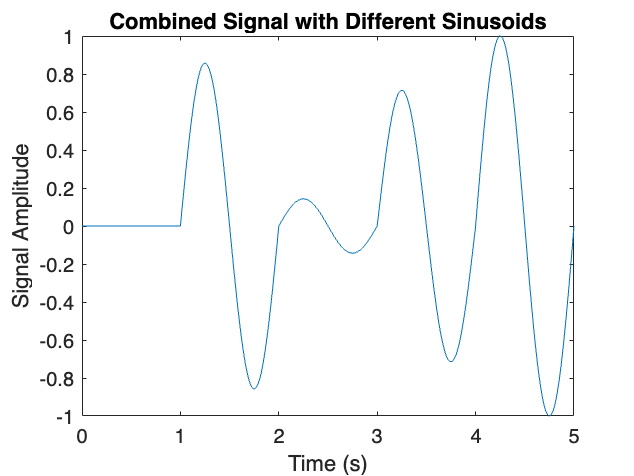

clear all

bit_rate = 3;

signal = createSignal(bit_rate);


decoding_map(signal, bit_rate);

000110001101111
Decoded string: ddp
